**Notes.**

Feel free to add more contents anytime. Just modify the 'Types of dimensionality reduction' section accordingly (25.03.14. Jungwoo).

# **Motivation**

## 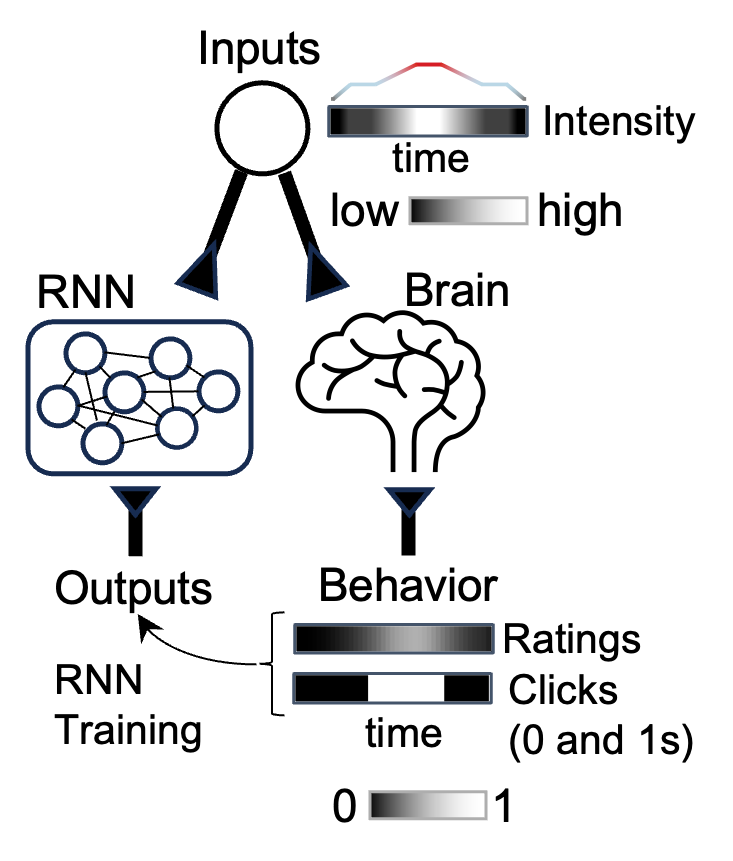

How can we compare the dynamics of two different systems (RNN and Brain)?

Let's first see what the data looks like.

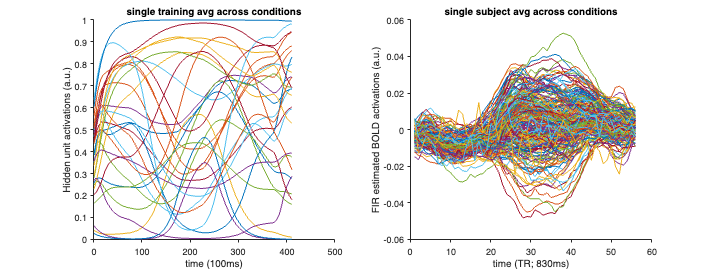

% Things to note:
%   For the RNN model, we used continuous RNN, which used dt as 100ms, and tau was 1000ms,
%   A tau of 1000ms is not biologically plausible, but we sticked with it for two reasons.
%       1) Behavioral plausibility
%       2) The Target of comparison is fMRI, which has slow dynamics.

close all; clear; clc; 
% cd('~/DimReduction')
addpath(genpath('functions'))
load('Dynamics.mat', 'RNNdat', 'MRIdat') 
    % RNNdat {n_condition x time x n_hiddenunits}                        x n_randseeds
    % MRIdat {n_condition x time x n_regions (Schaefer 265 regions)}     x n_subs
condmean_RNNdat = squeeze(mean(RNNdat{1}, 1)); % seed : 1
condmean_MRIdat = squeeze(mean(MRIdat{1}, 1)); % subj : 1
subplot 121; plot(condmean_RNNdat); box off; title('single training avg across conditions')
xlabel('time (100ms)'); ylabel('Hidden unit activations (a.u.)'); set(gca, 'TickDir', 'out')
subplot 122; plot(condmean_MRIdat); box off; title('single subject avg across conditions')
% For those who might be curious.
% subplot 122; plot(condmean_MRIdat - condmean_MRIdat(1, :)); box off;
xlabel('time (TR; 830ms)'); ylabel('FIR estimated BOLD activations (a.u.)'); set(gca, 'TickDir', 'out'); 
set(gcf, 'Position', [0 0 800 300])

It's hard to tell what is similar or not just by eyeballing the unit-level activations.

**We are going to use dimensionality reduction to find an appropriate space in which we can compare the two!**

# **Types of dimensionality reduction**

## **Un**supervised linear dimensionality reduction

- Principal Component Analysis (PCA; so many)                                                  DONE

- Factor Analysis ([1](https://www.nature.com/articles/nn.2501), [2](https://www.nature.com/articles/s41593-018-0095-3))

- Independent Component Analysis (ICA; [1](https://www.pnas.org/doi/10.1073/pnas.0905267106), [2](https://www.sciencedirect.com/science/article/abs/pii/S1053811915001822?via%3Dihub))

- Non-negative matrix Factorization (NNMF or NMF; [1](https://www.sciencedirect.com/science/article/abs/pii/S1053811914009756?via%3Dihub))

## Supervised linear dimensionality reduction

- Partial Least Squares (PLS; [1](https://www.nature.com/articles/s41593-022-01082-w))

- Canonical Correlation Analysis (CCA; [1](https://www.nature.com/articles/s41593-019-0555-4))

- Targeted Dimensionality Reduction (TDR; [1](https://www.nature.com/articles/nature12742), [2](https://www.science.org/doi/full/10.1126/sciadv.ado8230))                                                  DONE

- demixed PCA (dPCA; [1](https://elifesciences.org/articles/10989))

## Nonlinear dimensionality reduction

- t-distributed stochastic neighbor embedding (t-SNE; [1](https://proceedings.neurips.cc/paper_files/paper/2002/file/6150ccc6069bea6b5716254057a194ef-Paper.pdf))

- Locally Linear Embedding (LLE; [1](https://www.science.org/doi/10.1126/science.290.5500.2323))

- Isomap ([1](https://www.science.org/doi/10.1126/science.290.5500.2319))

#### **※ More in terms of dynamics **

- Dynamic Mode Decomposition - jPCA                                                                DONE

- Empirical Dynamic Modelling ([1](https://deepeco.ucsd.edu/resources/#page-content))

## Principal Component Analysis (PCA)

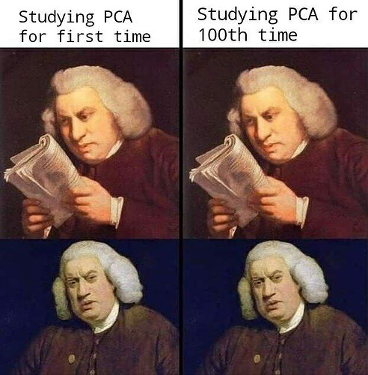 [Favorite PCA meme; thx to JJ from cocoan lab]

#### *PCA refers to "finding axes (principal components) that capture the directions of maximum variance." *

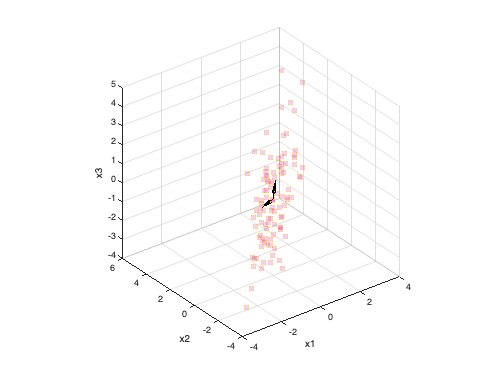

% Let's see in examples.

% minimal data generation. with 100 (observations) x 3 (features)
addpath(genpath('functions'))
rng('default')
n_data = 100;
x1     = randn(n_data, 1) + 1;
x2     = x1 + randn(n_data, 1) / 1.2 + 3;
x3     = x1 + randn(n_data, 1) / 1.5 + 2;
X      = [x1, x2, x3];
X0     = X - mean(X);

% draw.
close all;
scatter3(X0(:, 1), X0(:, 2), X0(:, 3), ...
    'MarkerFaceColor', [236 0 167]./255, 'MarkerEdgeColor', [247 224 0]./255, ...
    'MarkerFaceAlpha', 0.2); hold on;
xlabel('x1');ylabel('x2');zlabel('x3');

% PC calc. (see also side notes below)
[PCcoeff, ~] = pca(X, 'NumComponents', 2); 
arrow3([0 0 0; 0 0 0], PCcoeff(:, 1:2)');

In this rugby ball-like distributed data, the 1st PC finds the direction that the data are most stretched out (i.e., maximum variance). The 2nd PC finds the second most stretched direction among those that are **orthogonal** to the 1st PC.

#### **※ **Little side notes about PCA, EVD, and SVD.

Since `pca` performs eigenvalue decomposition (EVD) on the covariance matrix, substituting `X` with `X0` makes no difference. i.e., either `pca(X)` or `pca(X0)` is just the same. 

note that, 

isequal(cov(X), (X0'*X0) ./ (n_data-1))

ans = logical
   1


EVD is a special case of singular value decomposition (SVD). You just call it EVD when SVD is applied to covariance matrix. So using "`svd`" on X0 instead of function "`pca`" or "`eig`" on **X** would result in same eigenvectors.

[PCcoeff, ~] = pca(X, 'NumComponents', 2);
[S, V, D] = svd(X0, 'econ');
[PCcoeff(:, 1) D(:, 1)] % 

ans =     0.5134   -0.5134
    0.6183   -0.6183
    0.5950   -0.5950


What happens when SVD is applied to just **X**? It finds an axis that minimizes the distance between the axis and the data points. In fact, maximizing variance and minimizing the distance between the axis and the data points are the same thing (when data are mean centered), as detailed in the following [link](https://alexhwilliams.info/itsneuronalblog/2016/03/27/pca/).

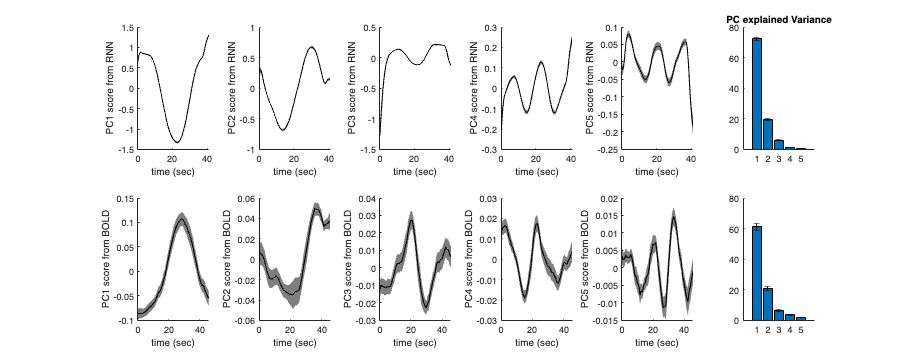

% How does it look like in the actual data?
clear;clc
load('Dynamics.mat', 'RNNdat', 'MRIdat') 
    % RNNdat {n_condition x time x n_hiddenunits} x n_randseeds
    % MRIdat {n_condition x time x n_regions}     x n_subs

numPC      = 5; warning off;
for seed_i = 1:numel(RNNdat)
    XX = squeeze(mean(RNNdat{seed_i}, 1)); % condition average
    [PCcoeff, PCscr, ~, ~, Expl] = pca(XX, 'Numcomponents', numPC);
    PCcoeffs.rnn(:, seed_i, :)   = PCcoeff;
    PCscrs.rnn(:, seed_i, :)     = PCscr;
    Expls.rnn(:, seed_i, :)      = Expl;
end

for sub_i = 1:numel(MRIdat)
    XX = squeeze(mean(MRIdat{sub_i}, 1)); % condition average
    [PCcoeff, PCscr, ~, ~, Expl] = pca(XX, 'Numcomponents', numPC);
    PCcoeffs.mri(:, sub_i, :)   = PCcoeff;
    PCscrs.mri(:, sub_i, :)     = PCscr;
    Expls.mri(:, sub_i, :)      = Expl;
end

% Since PCA is ignorant of direction, 
% will switch its sign based on the first seed and subject.

% % % 
intmodals = {'rnn', 'mri'};
for pc_i = 1:numPC
    for mod_i = 1:numel(intmodals)
        modPCscr   = PCscrs.(intmodals{mod_i})(:, :, pc_i);
        modPCcoeff = PCcoeffs.(intmodals{mod_i})(:, :, pc_i);

        corrmat  = corr(modPCscr);
        iidx     = corrmat(1, :) < 0;
        modPCscr(:, iidx) = -modPCscr(:, iidx);
        modPCcoeff(:, iidx) = -modPCcoeff(:, iidx);

        PCscrs.(intmodals{mod_i})(:, :, pc_i) = modPCscr;
        PCcoeffs.(intmodals{mod_i})(:, :, pc_i) = modPCcoeff;
    end
end
% % % 

% Let's now draw the PC scores
close all; set(gcf, 'Position', [0 0 1000 400])
for pc_i = 1:numPC
    rnndat   = PCscrs.rnn(:, :, pc_i);
    rnn_time = linspace(0, 41, size(rnndat, 1));

    mridat   = PCscrs.mri(:, :, pc_i);
    mri_time = 0:0.83:0.83*(size(mridat, 1)-1); % TR = 830 ms;

    mean_rnn = mean(rnndat, 2); ste_rnn  = ste(rnndat')';
    mean_mri = mean(mridat, 2); ste_mri  = ste(mridat')';

    subplot(2, numPC+1, pc_i);
    plotShadedErrorbar(rnn_time, mean_rnn, 'Error', ste_rnn); box off; xlim([0 max(rnn_time)])
    xlabel('time (sec)'); ylabel(sprintf('PC%d score from RNN', pc_i));

    subplot(2, numPC+1, pc_i+numPC+1);
    plotShadedErrorbar(mri_time, mean_mri, 'Error', ste_mri); box off; xlim([0 max(mri_time)])
    xlabel('time (sec)'); ylabel(sprintf('PC%d score from BOLD', pc_i));
end

subplot(2, 6, numPC+1);
drawmat = Expls.rnn(1:numPC, :);
meanmat = mean(drawmat, 2);     stemat  = ste(drawmat')';
bar(meanmat); hold on; box off;
erb = errorbar(1:numPC, meanmat, stemat); 
erb.Color = [0 0 0];    erb.LineStyle = 'none'; ylim([0 80]);
title('PC explained Variance')

subplot(2, 6, 2*(numPC+1));
drawmat = Expls.mri(1:numPC, :);
meanmat = mean(drawmat, 2);     stemat  = ste(drawmat')';
bar(meanmat); hold on; box off;
erb = errorbar(1:numPC, meanmat, stemat); 
erb.Color = [0 0 0];    erb.LineStyle = 'none';
ylim([0 80]);

Interesting! At least, we know that the RNN model is somehow related with the actual data, esp. in PC1 and 2. but now what...?

It doesn't give you *functional* interpretation of the axis. In other words, PCs may not correspond to meaningful or interpretable features in the original dataset.  

#### When and why is PCA used for?

- Denoising: Removes multicollinearity, handles redundancy ...

- Visualization: This actually applies to all dimensionality reduction techniques.

- Interpretation: PC1 is always PC1 regardless of how many components you extract (This is not the case in ICA or Factor Analysis). In addition, linear transformation applies between PC space and the voxel (or region) space, which makes it easier to interpret the PCs in the brain map.

- Predictive modelling: In fMRI data, the number of voxels far exceeds the nubmer of observations (whether it's time, trial, condition or subject). Fitting the linear model (such as regression using fMRI data as ***X***, behaviors as ***y***) would always results in overfitting (since it's [underdetermined](https://en.wikipedia.org/wiki/Underdetermined_system#:~:text=In%20mathematics%2C%20a%20system%20of,the%20concept%20of%20constraint%20counting.)). Applying PCA and then using the linear model prevents overfitting, (just like ridge or LASSO regression, but just in a different way).

## Targeted Dimensionality Reduction (TDR)

Not a formal mathematical definition. Key is **finding a dimension that is relevant to the task variable**.

For example, let's see the following task. [[Kim et al., 2024](https://www.science.org/doi/10.1126/sciadv.ado8230)]

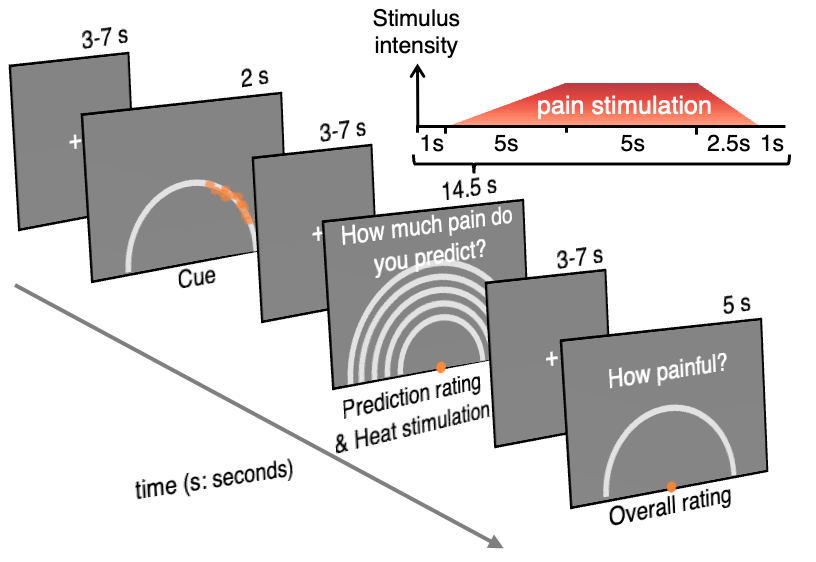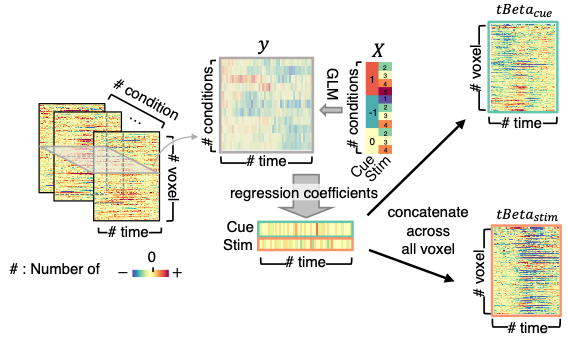 

                                    [Task]                                                              [Method]                                                                                                                                

In the task, we had two task features; cue and stimulus. There were three levels of cue (low, no, and high), which forms the expectation of the upcoming stimulus, and 5 levels of intensity (from 1 to 5). So each trial correspond to some level of cue and some level of stimulus. 

We used this cue and stimulus information as ***X*** and regress on neural activity on the corresponding dimension. The resulting regression coefficients can be regarded as **encoding weights **of each task feature. In Kim et al, we used PCA on the encoding coefficients to result in two different subspaces encoding either cue or stimulus information. But, the very [first paper](https://www.nature.com/articles/nature12742) (that I know of) that used the TDR selected the time point that has maximal norm from each matrix, and then QR decomposition to orthogonalize them.

TDR is particularly useful when the single trial has multiple task features (i.e., cue and stimulus) and want to sort out the two. If each task feature has more variables (e.g., three in cue and five in stimulus), it will result in more sensitive detection of the dimension. 

What should be our new ***X*** in the current study? Two features can be ratings and clicks.

The difference is that we have now task variable ***X*** in **both** **conditions** and **time. **(Note that, the upper example had only ***X*** in conditions, but not in time). So we can formalize the regression as the following.

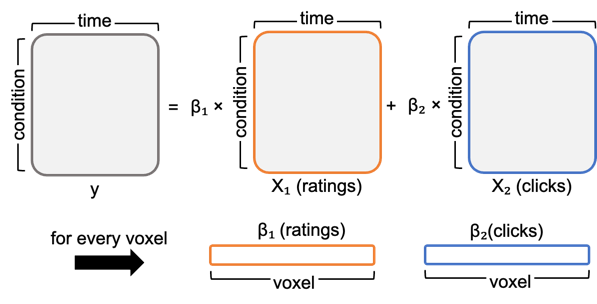

Let's look at the actual data.

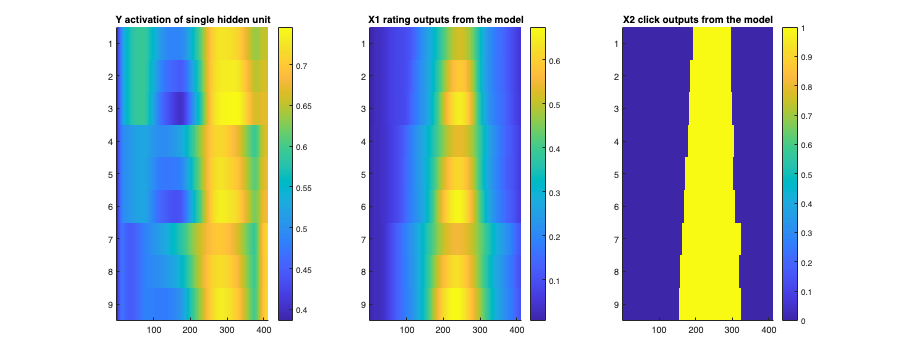

close all; clear; clc
load('Dynamics.mat', 'RNNdat', 'MRIdat') 
    % RNNdat {n_condition x time x n_hiddenunits} x n_randseeds
    % MRIdat {n_condition x time x n_regions}     x n_subs
load('Outputs.mat', 'RNNout', 'MRIout')
    % RNNout {n_condition x time x n_outlayers}   x n_randseeds
    %
    % MRIout.delayed: HRF delay considered
    %        {n_condition x time x 2 (rating, clicks)}  x n_subs
    % MRIout.nodelayed: HRF delay not considered
    %        {n_condition x time x 2 (rating, clicks)}  x n_subs
seedidx = 1; % 11
rnn_y  = RNNdat{seedidx}(:, :, 1); % single unit activation
rnn_X1 = RNNout{seedidx}(:, :, 1);
rnn_X2 = (RNNout{seedidx}(:, :, 3) - RNNout{seedidx}(:, :, 2)) > 0;
subplot 131; imagesc(rnn_y);  box off; title('Y activation of single hidden unit'); colorbar;
subplot 132; imagesc(rnn_X1); box off; title('X1 rating outputs from the model'); colorbar;
subplot 133; imagesc(rnn_X2); box off; title('X2 click outputs from the model'); colorbar;
set(gcf, 'Position', [0 0 1000 400])

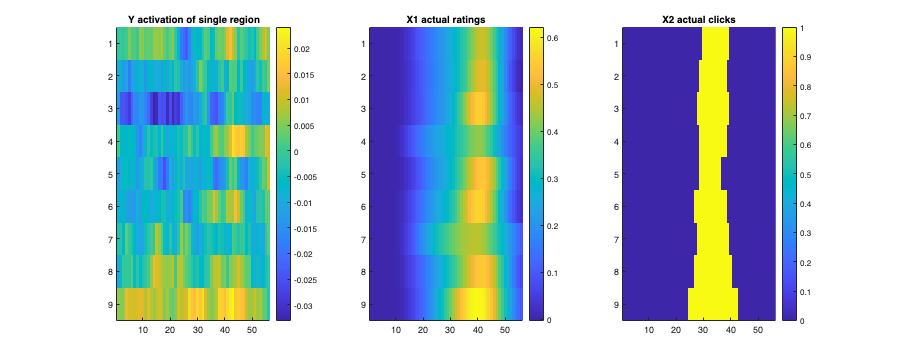

close all;
subidx = 1; % 11
mri_y  = MRIdat{subidx}(:, :, 1);        % single unit activation
mri_X1 = MRIout.delayed{subidx}(:, :, 1);
mri_X2 = MRIout.delayed{subidx}(:, :, 2);
subplot 131; imagesc(mri_y);  box off; title('Y activation of single region'); colorbar;
subplot 132; imagesc(mri_X1); box off; title('X1 actual ratings'); colorbar;
subplot 133; imagesc(mri_X2); box off; title('X2 actual clicks'); colorbar;
set(gcf, 'Position', [0 0 1000 400])

Let's do the regression process.

% For RNN
rnn_beta1s = cell(numel(RNNdat), 1);
rnn_beta2s = cell(numel(RNNdat), 1);
for seed_i = 1:numel(RNNdat)
    n_unit = size(RNNdat{seed_i}, 3);

    for unit_i = 1:n_unit
        rnn_y  = RNNdat{seed_i}(:, :, unit_i); % single unit activation
        rnn_X1 = RNNout{seed_i}(:, :, 1);
        rnn_X2 = (RNNout{seed_i}(:, :, 3) - RNNout{seed_i}(:, :, 2)) > 0;

        betas  = glmfit([rnn_X1(:), rnn_X2(:)], rnn_y(:));
        rnn_beta1s{seed_i}(unit_i, :) = betas(2, :); % betas(1, :) correspond to intercept
        rnn_beta2s{seed_i}(unit_i, :) = betas(3, :);
    end
end

% For MRI
delay_consider = true;
mri_beta1s = cell(numel(MRIdat), 1);
mri_beta2s = cell(numel(MRIdat), 1);
for sub_i = 1:numel(MRIdat)
    n_unit = size(MRIdat{sub_i}, 3);

    for unit_i = 1:n_unit
        mri_y  = MRIdat{sub_i}(:, :, unit_i); % single region activation
        if delay_consider
            mri_X1 = MRIout.delayed{sub_i}(:, :, 1);
            mri_X2 = MRIout.delayed{sub_i}(:, :, 2);
        else
            mri_X1 = MRIout.nodelayed{sub_i}(:, :, 1);
            mri_X2 = MRIout.nodelayed{sub_i}(:, :, 2);
        end

        betas  = glmfit([mri_X1(:), mri_X2(:)], mri_y(:));
        mri_beta1s{sub_i}(unit_i, :) = betas(2, :); % betas(1, :) correspond to intercept
        mri_beta2s{sub_i}(unit_i, :) = betas(3, :);
    end
end

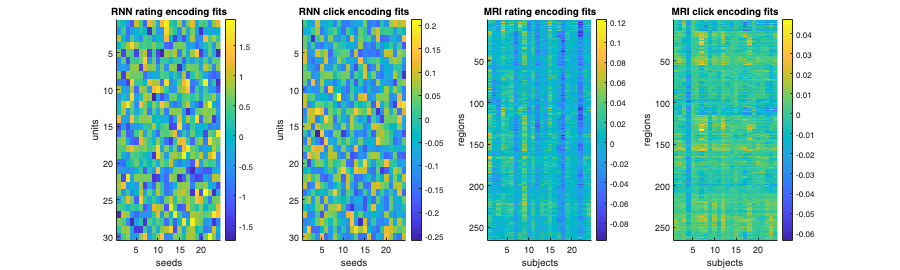

% Let's see how overall regression coefficients look like.
close all;
subplot 141; imagesc(cat(2, rnn_beta1s{:})); box off; title('RNN rating encoding fits'); 
xlabel('seeds'); ylabel('units'); colorbar
subplot 142; imagesc(cat(2, rnn_beta2s{:})); box off; title('RNN click encoding fits');
xlabel('seeds'); ylabel('units'); colorbar
subplot 143; imagesc(cat(2, mri_beta1s{:})); box off; title('MRI rating encoding fits'); 
xlabel('subjects'); ylabel('regions'); colorbar
subplot 144; imagesc(cat(2, mri_beta2s{:})); box off; title('MRI click encoding fits'); 
xlabel('subjects'); ylabel('regions'); colorbar
set(gcf, 'Position', [0 0 1000 300])

Let's see how dynamics look like after projecting the data onto the space.

% TDR implementation
do_qr = false;
rnn_rate_space = cellfun(@(x) x ./ norm(x), rnn_beta1s, 'UniformOutput', false);
rnn_clk_space = cellfun(@(x) x ./ norm(x), rnn_beta2s, 'UniformOutput', false);
mri_rate_space = cellfun(@(x) x ./ norm(x), mri_beta1s, 'UniformOutput', false);
mri_clk_space = cellfun(@(x) x ./ norm(x), mri_beta2s, 'UniformOutput', false);

angles_btw_space.rnn = NaN(numel(RNNdat), 1);
angles_btw_space.mri = NaN(numel(MRIdat), 1);
rnnprj               = cell(numel(RNNdat), 1);
for seed_i = 1:numel(RNNdat)
    rnndat = RNNdat{seed_i};
    sp1                = rnn_rate_space{seed_i};
    sp2                = rnn_clk_space{seed_i};
    angles_btw_space.rnn(seed_i) = acosd(sp1'*sp2);
    if do_qr
        [Q, ~]         = qr([sp1 sp2]);
        rateclk_space  = Q(:, 1:2);
    else
        rateclk_space = [sp1 sp2];
    end

    for cond_i = 1:size(rnndat, 1)
        conddat  = squeeze(rnndat(cond_i, :, :));
        conddat0 = conddat - mean(conddat);
        rnnprj{seed_i}(cond_i, :, :) = conddat0 * rateclk_space; % projecting data per condition.
    end
end

mriprj               = cell(numel(MRIdat), 1);
for sub_i = 1:numel(MRIdat)
    mridat = MRIdat{sub_i};
    sp1                = mri_rate_space{sub_i};
    sp2                = mri_clk_space{sub_i};
    angles_btw_space.mri(sub_i) = acosd(sp1'*sp2);
    if do_qr
        [Q, ~]         = qr([sp1 sp2]);
        rateclk_space  = Q(:, 1:2);
    else
        rateclk_space = [sp1 sp2];
    end

    for cond_i = 1:size(mridat, 1)
        conddat  = squeeze(mridat(cond_i, :, :));
        conddat0 = conddat - mean(conddat);
        mriprj{sub_i}(cond_i, :, :) = conddat0 * rateclk_space; % projecting data per condition.
    end
end

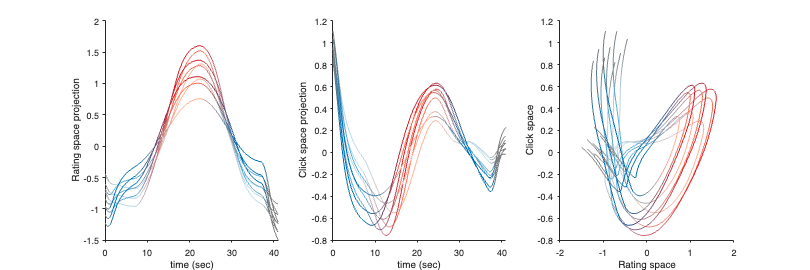

% Let's see in RNN
close all
seed_i = 2; % % Try seed 3 as well. 
for cond_i = 1:9
    rnndraw = squeeze(rnnprj{seed_i}(cond_i, :, :));
    n_time  = size(rnndraw, 1);
    x_is    = linspace(0, 41, n_time);
    rnnclrs = graded_colors(((n_time - 1) / 41) * 2 + n_time-1);
    rnnclrs = rnnclrs(:, (((n_time - 1) / 41) * 2 + 1):end, :); % getting the graded colors 
    condclr = squeeze(rnnclrs(cond_i, :, :));

    subplot 131;
    plot_graded(x_is', rnndraw(:, 1), condclr); hold on; box off; set(gca, 'TickDir', 'out');
    xlabel('time (sec)'); ylabel('Rating space projection'); xlim([0 max(x_is)]);
    subplot 132;
    plot_graded(x_is', rnndraw(:, 2), condclr); hold on; box off; set(gca, 'TickDir', 'out');
    xlabel('time (sec)'); ylabel('Click space projection');  xlim([0 max(x_is)]);
    subplot 133;
    plot_graded(rnndraw(:, 1), rnndraw(:, 2), condclr); hold on; box off; set(gca, 'TickDir', 'out');
    xlabel('Rating space'); ylabel('Click space');
end
set(gcf, 'Position', [0 0 900 300])

This also looks interesting. So projections on the rating space seems like PC1 scores and those on the click space seems like PC2.

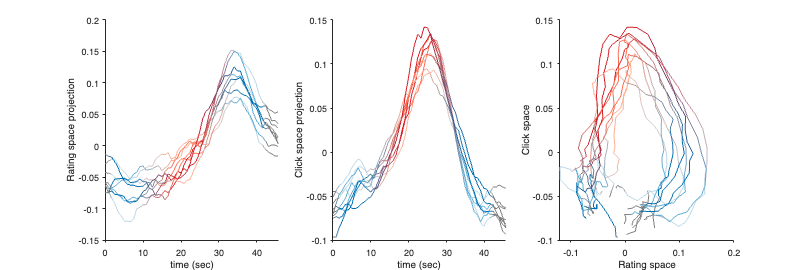

% Let's see in fMRI data
%
% Things to note,
%   MRI session has only reports of clicks, but no ratings. 
%   (To reduce the motor and visual effects of actual ratings.)
%   
%   So here, the click timings are from in scanner, and ratings are from out scanner,
%   which might be bit controversial.

close all
sub_i = 1:24; % % can modify this part to see subj level dynamics. e.g., sub_i = 1;
for cond_i = 1:9
    mridraw_ = cellfun(@(x) squeeze(x(cond_i, :, :)), mriprj(sub_i), 'UniformOutput', false);
    mridraw  = mean(cat(3, mridraw_{:}), 3);
    n_time   = size(mridraw, 1);
    x_is     = 0:0.83:0.83*(n_time-1);
    mriclrs  = graded_colors(((n_time - 1) / 41) * 2 + n_time);
    mriclrs  = mriclrs(:, (((n_time - 1) / 41) * 2 + 1):end, :); % getting the graded colors 
    condclr  = squeeze(mriclrs(cond_i, :, :));

    subplot 131;
    plot_graded(x_is', mridraw(:, 1), condclr); hold on; box off; set(gca, 'TickDir', 'out');
    xlabel('time (sec)'); ylabel('Rating space projection'); xlim([0 max(x_is)]);
    subplot 132;
    plot_graded(x_is', mridraw(:, 2), condclr); hold on; box off; set(gca, 'TickDir', 'out');
    xlabel('time (sec)'); ylabel('Click space projection');  xlim([0 max(x_is)]);
    subplot 133;
    plot_graded(mridraw(:, 1), mridraw(:, 2), condclr); hold on; box off; set(gca, 'TickDir', 'out');
    xlabel('Rating space'); ylabel('Click space');
end
set(gcf, 'Position', [0 0 900 300])

So far, we can infer that how the brain encodes rating and click information is different from those in RNNs.

Since the current code did not use QR decomposition (ctrl + f to find `do_qr`), the axes for rating and click are not orthogonal.

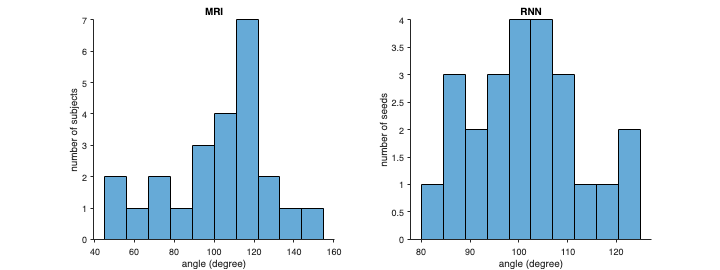

close all;
subplot 121; histogram(angles_btw_space.mri, 10); xlabel('angle (degree)'); ylabel('number of subjects'); title('MRI') 
set(gca, 'TickDir', 'out'); box off;
subplot 122; histogram(angles_btw_space.rnn, 10); xlabel('angle (degree)'); ylabel('number of seeds'); title('RNN') 
set(gca, 'TickDir', 'out'); box off;
set(gcf, 'Position', [0 0 800 300])

#### When and why is TDR used for?

- Interpretability: Interpretable not in terms of its variance like PCA, but we can see how the temporal information flows (or is represented) in the specific dimension of interest.

- Computational insights: We can investigate the dynamics itself, but also the relationship between the subspace (e.g., angles) for computational interpretation ([1](https://www.nature.com/articles/nn.3643), [2](https://www.nature.com/articles/s41586-024-08548-w)).

One shortcoming to note is that, unless the data is super random, it will somehow find the dimension that seem to reflect the information of interest, but the resulting dimension doesn't guarantee how stable or reliable it is.

## Dynamic Mode Decomposition (DMD)

Almost copy and paste of the [link](https://www.youtube.com/watch?v=sQvrK8AGCAo).

Let's say we have voxel time series ***X,***  size of `n_voxel × n_time. `

In the following equation, DMD is essentially finding ***A*** matrix, but with a few important components of ***X****.*


$$X{\prime} \approx A X$$


***X' ***is a next time steps of ***X*** (or derivative of the time dimension in the continuous system)***. ***So the ***A*** contains information of how the current state of ***X ***will move or change in the very next time point. To be precise, The element in the *i *th row and *j *th column of ***A*** indicates how the current state's *j *th element affects *i* th element of the next state. 

If we are to use ***X ***as a whole-brain voxel, size of ***A*** can be massive. What DMD is trying to do is, "okay, under the assumption of there being a few dominant components (or factors) in this current data, let's just use those dominant ones to have more concise ***A ***matrix. 

**※ Side notes.**

The simple equation is assuming **autonomous** **linear **dynamical systems (autonomous in that it doesn't have any external input; linear in that it is a matrix multiplication), but it can use kernel to introduce non-linearity in the system. 

This link has more and far beyond about [DMD](http://dmdbook.com/). 


$$\( X = U \Sigma V^* \quad X' = A U \Sigma V^* \)

\( U^* X' V \Sigma^{-1} = U^* A U = \tilde{A} \)

\( \tilde{A} W = W \Lambda \)

\( \Phi = X' V \Sigma^{-1} W \)$$


"A tilda" is a linear best fit of dynamical systems, which tells me how "dominant modes", which are "phi" in this case, evolve in time.

For future prediction, we can use the following. (***b ***sets an initial condition) 


$$x(t) = \Phi \Lambda^t b$$


Let's see in the actual code. 

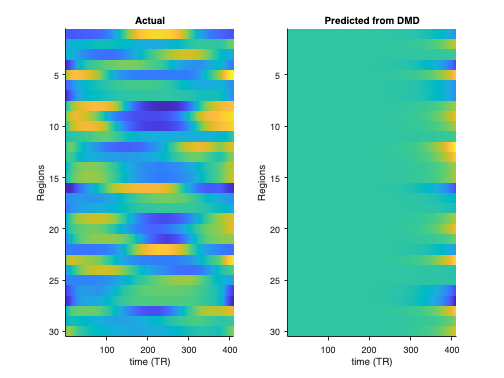

n_modes = 5; % can vary
Atilds  = [];
load('Dynamics.mat', 'RNNdat')
for seed_i = 1:numel(RNNdat)
    tdat = RNNdat{seed_i};
    for cond_i = 1:size(tdat, 1)
        Xo   = squeeze(tdat(cond_i, :, :))';
        X    = Xo(:, 1:end-1);
        Xprm = Xo(:, 2:end);

        [U, S, V] = svd(X, 'econ');
        Umod  = U(:, 1:n_modes);
        Smod  = S(1:n_modes, 1:n_modes);
        Vmod  = V(:, 1:n_modes);

        Atild = Umod' * Xprm * Vmod * inv(Smod);
        [W, lambda] = eig(Atild);    % 
        Phi = Xprm*Vmod*inv(Smod)*W; 
        % It's actually A*Umod*W (without an A)

        % "Phi" is a mode in the original space (i.e., size(X, 1) space).
        %  but since Atild is not positive definite (not cov matrix),
        % "Phi" doesn't always result in real number, which gets hard to interpret...

        x0 = X(:,1);   % First snapshot as the initial condition
        b  = Phi \ x0; % Solve for initial coefficients
        t_max = 410;
        
        % Predict future states
        X_future = zeros(size(X,1), t_max);
        for t = 1:t_max
            X_future(:,t) = Phi * (lambda^t) * b;
        end
        % subplot 121; imagesc(X); subplot 122; imagesc(real(X_future))

        % If the leading eigenvalue > 1, the system will eventually inflate, and
        % otherwise, shrink, which is not expected in our current data.
        % How can we make use of it then?

        Atilds(seed_i, cond_i, :) = Atild(:);        
    end
end
close all;
subplot 121; imagesc(X); xlabel('time (TR)'); ylabel('Regions'); title('Actual'); box off; set(gca, 'TickDir', 'out');
subplot 122; imagesc(real(X_future)); xlabel('time (TR)'); ylabel('Regions'); title('Predicted from DMD'); box off; set(gca, 'TickDir', 'out');

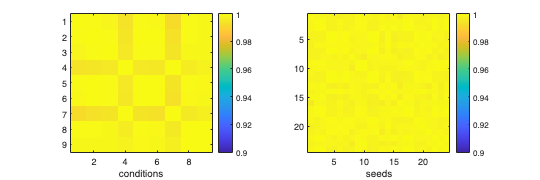

% Let's see how Atild is similar across different RNN seeds and conditions. 

% Across conditions
close all;
subplot 121;
seed_i = 1;
imagesc(corr(squeeze(Atilds(seed_i, :, :))')); colorbar; clim([0.9 1]);
xlabel('conditions');

% Across seeds
cond_i = 3;
subplot 122;
imagesc(corr(squeeze(Atilds(:, cond_i, :))')); colorbar; clim([0.9 1])
xlabel('seeds');
set(gcf, 'Position', [0 0 600 200])

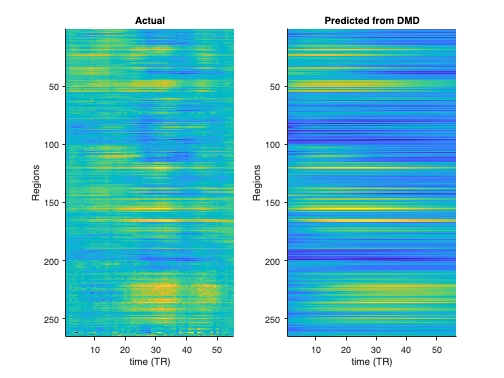

% Same but in MRI data.
n_modes = 5; % can vary
Atilds  = [];
load('Dynamics.mat', 'MRIdat')
for sub_i = 1:numel(MRIdat)
    tdat = MRIdat{sub_i};
    for cond_i = 1:size(tdat, 1)
        Xo   = squeeze(tdat(cond_i, :, :))';
        X    = Xo(:, 1:end-1);
        Xprm = Xo(:, 2:end);

        [U, S, V] = svd(X, 'econ');
        Umod  = U(:, 1:n_modes);
        Smod  = S(1:n_modes, 1:n_modes);
        Vmod  = V(:, 1:n_modes);

        Atild = Umod' * Xprm * Vmod * inv(Smod);
        [W, lambda] = eig(Atild);    % 
        Phi = Xprm*Vmod*inv(Smod)*W; 
        % It's actually A*Umod*W (without an A)

        % "Phi" is a mode in the original space (i.e., size(X, 1) space).
        %  but since Atild is not positive definite (not cov matrix),
        % "Phi" doesn't always result in real number, which gets hard to interpret...

        x0 = X(:,1);   % First snapshot as the initial condition
        b  = Phi \ x0; % Solve for initial coefficients
        t_max = 56;
        
        % Predict future states
        X_future = zeros(size(X,1), t_max);
        for t = 1:t_max
            X_future(:,t) = Phi * (lambda^t) * b;
        end

        Atilds(sub_i, cond_i, :) = Atild(:);        
    end
end

close all;
subplot 121; imagesc(X); xlabel('time (TR)'); ylabel('Regions'); title('Actual'); box off; set(gca, 'TickDir', 'out');
subplot 122; imagesc(real(X_future)); xlabel('time (TR)'); ylabel('Regions'); title('Predicted from DMD'); box off; set(gca, 'TickDir', 'out');

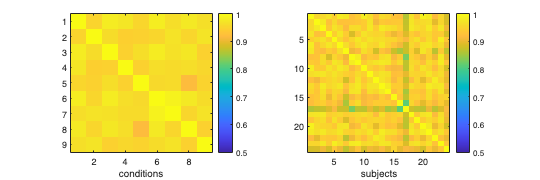

% Let's see how Atild is similar across different subjects and conditions. 

% Across conditions
close all;
subplot 121;
sub_i = 1;
imagesc(corr(squeeze(Atilds(sub_i, :, :))')); colorbar; clim([0.5 1]);
xlabel('conditions');

% Across subjects
cond_i = 8;
subplot 122;
imagesc(corr(squeeze(Atilds(:, cond_i, :))')); colorbar; clim([0.5 1])
xlabel('subjects');
set(gcf, 'Position', [0 0 600 200])

#### When and why is DMD used for?

- Extracts dominant temporal modes, without calculating the full system.

- It's different from PCA in that PCA doesn't take into temporal information into account. It's more like a PCA + Fourier transform.

- The resulting "mode" in $\phi$, is quite hard to interpret, since there are imaginery numbers in them. For those who care about the spatial maps of the brain, this might be a tricky part. 

One idea is that, assuming autonomous dynamical systems might be more plausible in a shorter time series (it's saying temporally local linear dynamics), so calculaing $\tilde{A}_{t}$ multiple times in a shorter time window may provide better estimates of overall nonlinear dynamics. 

### **※ **jPCA

From [https://www.nature.com/articles/nature11129.](https://www.nature.com/articles/nature11129.) (One of the most well guided [code](https://www.dropbox.com/scl/fo/duf5zbwcibsux467c6oc9/AIN-ZiFsy2Huyh8h7VMdL7g?rlkey=3o5axmq5hirel4cij7g64jc0r&e=1&dl=0) instructions I've ever seen).

What the name stands for is quite mysterious but I am assuming that it followed the author John P. Cunningham's name (correct me if I am wrong).

What it basically assumes (autonomous dynamical systems) is very same with the DMD.


$$X{\prime} \approx A X$$


The size of $X$ is here `n_neuron x n_time`. The fundamental difference is that while DMD focuses on finding concise $\tilde{A}$, jPCA calculates $A$first, and then applies eigenvalue decomposition on $A$matrix. So this is also very likely to have imaginary eigenvectors, and it solves it via calculating $A$ with additional constraints.

So the functionality is quite different from DMD, as the purpose of jPCA is much simpler: finding a dimension that reflects the dynamics. It's descriptive rather than predictive.